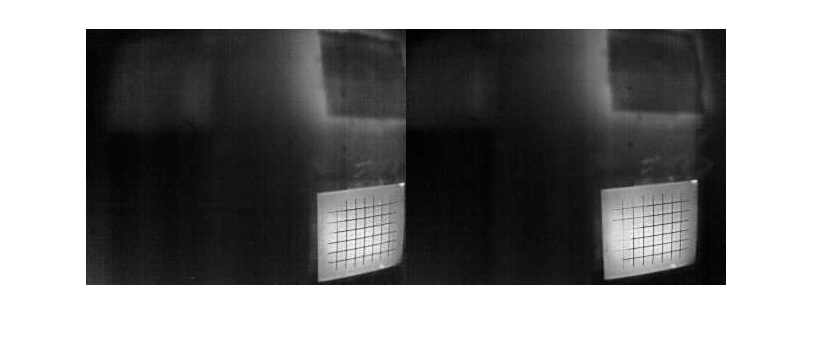

rgbLPath = "./recode/check10_10.jpg";
rgbRPath = "./recode/check30_10.jpg";

rgbL = imread(rgbLPath);
rgbR = imread(rgbRPath);


imshowpair(rgbL, rgbR, 'montage')

%[rgbL_rec1, rgbR_rec1] = rectifyStereoImages(rgbL(:,:,1), rgbR(:,:,1), stereoParams);
%[rgbL_rec2, rgbR_rec2] = rectifyStereoImages(rgbL(:,:,2), rgbR(:,:,2), stereoParams);
%[rgbL_rec3, rgbR_rec3] = rectifyStereoImages(rgbL(:,:,3), rgbR(:,:,3), stereoParams);
[rgbL_rec_gray, rgbR_rec_gray] =rectifyStereoImages(rgbL(:,:,1), rgbR(:,:,1), stereoParams);
%rgbL_rec = cat(3, rgbL_rec1, rgbL_rec2, rgbL_rec3);
%rgbR_rec = cat(3, rgbR_rec1, rgbR_rec2, rgbR_rec3);

%rgbL_rec_gray = rgb2gray(rgbL_rec);
%rgbR_rec_gray = rgb2gray(rgbR_rec);

%imshowpair(rgbL_rec, rgbR_rec, 'montage')

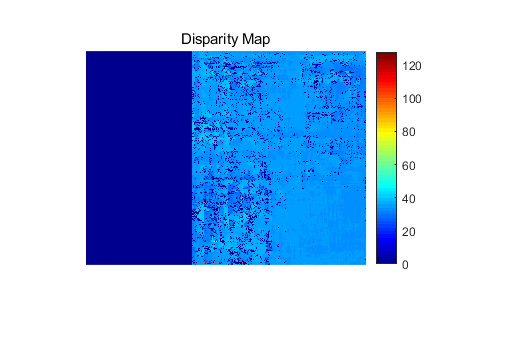

disparityRange = [0 128];
disparityMap = disparitySGM(rgbL_rec_gray,rgbR_rec_gray,'DisparityRange',disparityRange,'UniquenessThreshold',5);
figure
imshow(disparityMap,disparityRange)
title('Disparity Map')
colormap jet
colorbar

points3D = reconstructScene(disparityMap, stereoParams);
points3D = points3D ./ 1000;
ptCloud = pointCloud(points3D, 'Color', rgbL_rec);

% Create a streaming point cloud viewer
player3D = pcplayer([-3, 3], [-3, 3], [0, 8], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(player3D, ptCloud);

Z=ones(258,338);
Z=(Z)./disparityMap;
Z=Z*f*b;

m=Z(:,129:end)

m = 258×210 single 행렬
	1.0e+03 *

    1.0603    1.0603    1.0557    1.0628    1.0608    1.0608    1.0608    1.0608    1.0565    1.0521    1.0581    1.0642    1.0608    1.0612    1.0639    1.0599    1.0642    1.0660    1.0619    1.0694    1.0705    1.0660    1.0642    1.0603    1.0642    1.0581    1.0705    1.0654    1.0603    1.0583    1.0642    1.0666    1.0632    1.0632    1.0632    1.0632    1.0625    1.0675    1.0646    1.0608    1.0623    1.0613    1.0663    1.0623    1.0613    1.0608    1.0647    1.0613    1.0632    1.0632
    1.0020    1.0000    0.9949    1.0009    1.0490    1.0415    1.0101    0.9975    1.0007    0.9962    0.9873    0.9700    0.9541    0.9970    0.9953    0.9984    1.0626    1.0803       NaN    0.9978    0.9872    0.9944    0.9835    0.9969    0.9929    1.0032    0.9870    1.0161    1.0056    1.0145    1.0006    1.0396    1.0349    1.0248    1.0238    1.0235    1.0328    1.0354    1.0461    1.0369    1.0318    1.0304    1.0446    1.0344    1.0261    1.0261    1

mask = m~=inf;
mm = m(mask)

mm = 54180×1 single 열 벡터
	1.0e+03 *

    1.0603
    1.0020
    0.9763
    0.9949
    0.9885
    0.9844
    0.9903
    1.0373
    1.0385
    1.0516


M=mean(mm,"all")

M = single
NaN

m=Z(234:258,156:338);
mask = m~=inf;
mm = m(mask)

mm = 4575×1 single 열 벡터
	1.0e+03 *

       NaN
    0.8503
    0.8652
       NaN
       NaN
       NaN
       NaN
    1.0524
    1.0395
    1.0400


MM=mean(mm,"all");

sorted=sort(mm)

sorted = 8836×1 single 열 벡터
	1.0e+03 *

    0.9235
    0.9279
    0.9294
    0.9342
    0.9359
    0.9420
    0.9423
    0.9431
    0.9473
    0.9478


%top=sorted(1:1253765,:)
sorted_mean=mean(sorted,"all")

sorted_mean = single
1.0202e+03

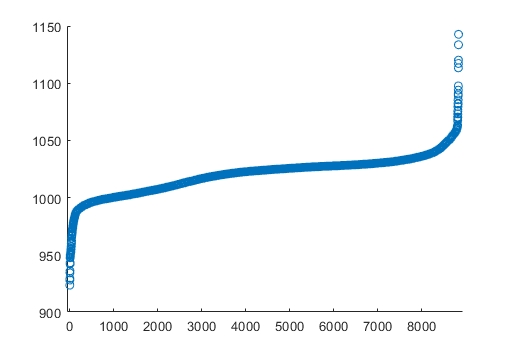

%x=[1:1:1253765]
%y=top(x)
scatter([1:8836],sorted)

%xlim([1,2000]);
